# Partial-Fraction Expansion of IIR Lowpass Filter

Compute the partial-fraction expansion corresponding to the third-order IIR lowpass filter described by the transfer function


$$H(z)={{0.05634(1+z^{-1})(1-1.0166z^{-1}+z^{-2})}
\over{(1-0.683z^{-1})(1-1.4461z^{-1}+0.7957z^{-2})}}.$$


Express the numerator and denominator as polynomial convolutions.

b0 = 0.05634;
b1 = [1  1];
b2 = [1 -1.0166 1];
a1 = [1 -0.683];
a2 = [1 -1.4461 0.7957];

b = b0*conv(b1,b2)

b =     0.0563   -0.0009   -0.0009    0.0563


a = conv(a1,a2)

a =     1.0000   -2.1291    1.7834   -0.5435


Compute the residues, poles, and direct terms of the partial-fraction expansion.

[r,p,k] = residuez(b,a)

r =   -0.1153 - 0.0182i
  -0.1153 + 0.0182i
   0.3905 + 0.0000i


p =    0.7230 + 0.5224i
   0.7230 - 0.5224i
   0.6830 + 0.0000i


k = -0.1037

Plot the poles and zeros of the transfer function and overlay the poles you just found.

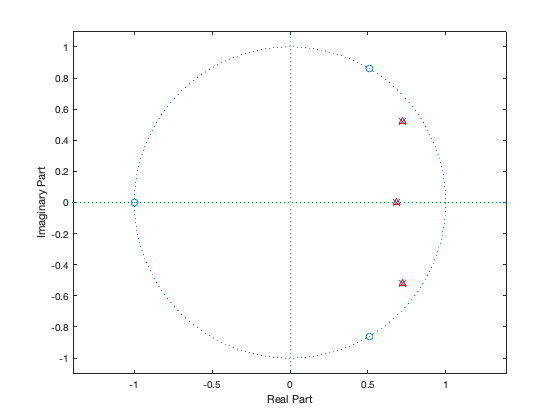

zplane(b,a)
hold on
plot(p,'^r')
hold off

Use `residuez` again to reconstruct the transfer function.

[bn,an] = residuez(r,p,k)

bn =     0.0563   -0.0009   -0.0009    0.0563


an =     1.0000   -2.1291    1.7834   -0.5435


*Copyright 2012 The MathWorks, Inc.*

Graph Frequency Response of IIR Filter

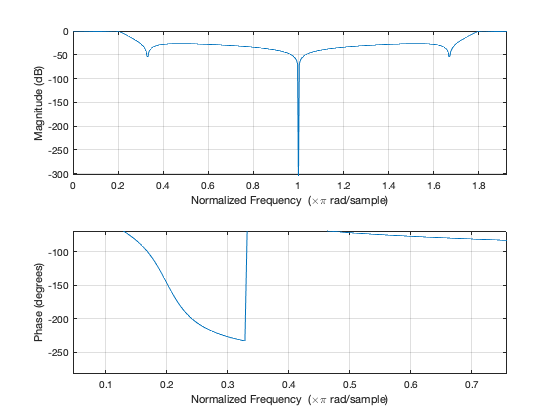

freqz(bn,an,'whole')

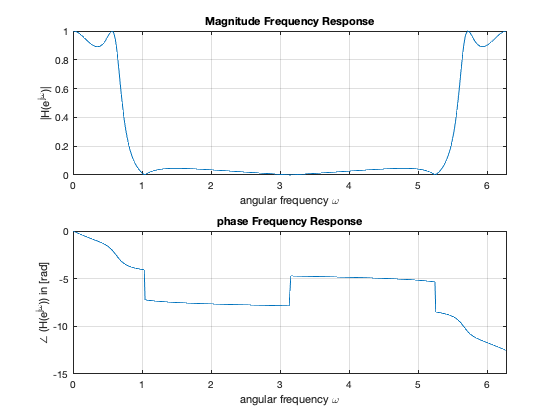

[H,w]=freqz(bn,an,'whole');

figure
subplot(211)
plot(w,abs(H))
xlim([0, 2*pi])
xlabel('angular frequency \omega')
ylabel('|H(e^{j\omega})|')
title('Magnitude Frequency Response')
grid
subplot(212)
plot(w,phase(H))
xlim([0, 2*pi])
xlabel('angular frequency \omega')
ylabel('\angle (H(e^{j\omega})) in [rad]')
title('phase Frequency Response')
grid